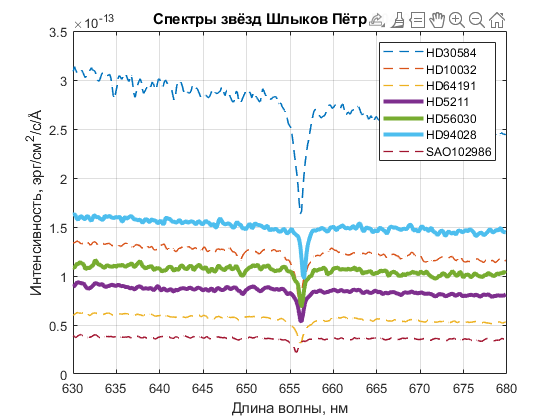

spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');
nst = size(starNames, 1);
nobs = size(spectra, 1);
lambdaEnd = lambdaStart + (nobs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';
speedmass = zeros(nst, 1);
speedOfLight = 299792.458;
lambdaPr = 656.28;

for i = 1:1:nst
    s = spectra(:, i);
    [sHa, ind] = min(s);
    lambdaHa = lambda(ind);
    z = (lambdaHa / lambdaPr) - 1;
    speed = z * speedOfLight;
    speedmass(i, 1) = speed;
end
speed = speedmass;

movaway = starNames(speedmass > 0);

fg = figure;
for i = 1:1:nst
    s = spectra(:, i);
    if speedmass(i, 1) <= 0
        plot(lambda, s, "--", "LineWidth", 1)
    else
        plot(lambda, s, "LineWidth", 3)
    end
    hold on
end
title("Спектры звёзд Шлыков Пётр Б04-004")
legend(starNames)
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
set(fg, "Visible", "on")
grid on
hold off
saveas(fg, "спектры.png")